# Metode de interpolare bazate pe diferente divizate

## Probleme

P1. Implementati o rutina pentru calculul valorilor polinomului de interpolare Hermite cu noduri duble, dandu-se punctele in care se face evaluarea, nodurile, valorile functiei si ale derivatei in noduri.

% definim nodurile de interpolare x_i
nodes = [0, 1, 2];
% definim valorile functiei f(x_i) in noduri (aici, valorile pentru e^x)
f_values = [1, 2.71828, 7.38906]; % e^0=1, e^1 approx 2.71828, e^2 approx 7.38906
% definim valorile derivatei f'(x_i) in noduri (pentru e^x, f'(x) = e^x)
f_prime_values = [1, 2.71828, 7.38906];
% definim punctul x in care dorim sa evaluam polinomul de interpolare hermite
x_eval = 0.5;

% apelam functia de interpolare hermite cu datele definite mai sus
rezultat = hermite_interpolation(x_eval, nodes, f_values, f_prime_values);
% afisam rezultatul interpolarii in punctul x_eval
fprintf('valoarea interpolata la x = %.2f este: %.6f\n', x_eval, rezultat);

valoarea interpolata la x = 0.50 este: 1.648208


P2. Reprezentati pe acelasi grafic f si polinomul sau de interpolare Hermite.

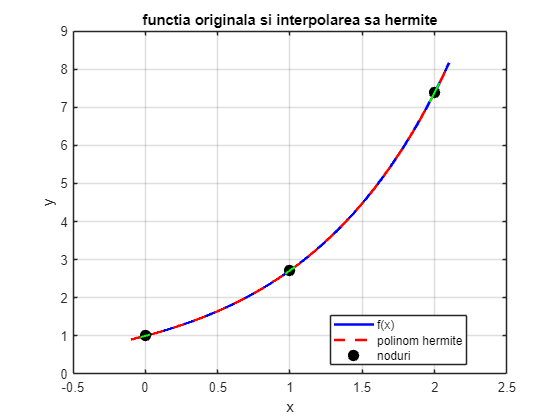

% definim nodurile de interpolare x_i
nodes = [0, 1, 2];
% definim functia originala f(x) folosind un handle de functie (anonymous function)
% in acest caz, f(x) = e^x
f = @(x) exp(x);
% definim derivata functiei f'(x) folosind un handle de functie
% pentru e^x, derivata este tot e^x
f_prime = @(x) exp(x);
% calculam valorile functiei f(x_i) in nodurile definite
f_values = f(nodes);
% calculam valorile derivatei f'(x_i) in nodurile definite
f_prime_values = f_prime(nodes);

% apelam functia pentru a reprezenta grafic interpolarea hermite
% ea va plota functia originala, polinomul hermite si nodurile
plot_hermite_interpolation(nodes, f_values, f_prime_values, f);

P3. Scrieti o rutina care reprezinta grafic o cubica parametrica Hermite (o curba care trece prin doua puncte date si are in acele puncte tangente date).

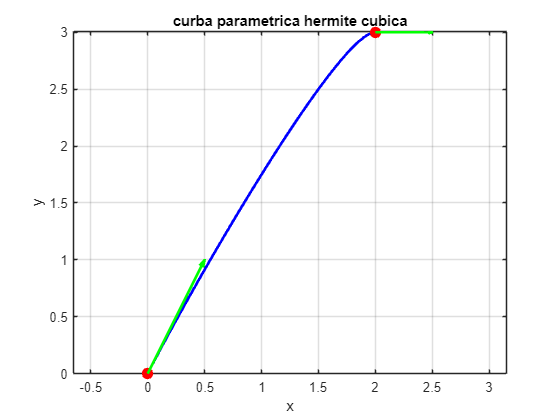

p1 = [0, 0];    % primul punct
p2 = [2, 3];    % al doilea punct
t1 = [1, 2];    % tangenta in primul punct
t2 = [1, 0];    % tangenta in al doilea punct

plot_cubic_hermite_curve(p1, p2, t1, t2);

## Probleme practice

P1. Pentru f(x) = e^x si nodurile de interpolare 0, 1, 2, aproximati f(0.25) prin interpolare Hermite si comparati rezultatul cu cel obtinut prin interpolare Lagrange. Dati o delimitare a erorii. Comparati cu rezultatul furnizat de software-ul utilizat.

% compararea interpolarii hermite si lagrange pentru e^x
clear; % sterge toate variabilele din workspace
clc; % curata fereastra de comanda

% definim nodurile si functia
nodes = [0, 1, 2]; % vectorul cu nodurile de interpolare x_i
f = @(x) exp(x); % definim functia f(x) = e^x folosind un handle de functie
f_prime = @(x) exp(x); % definim derivata f'(x) = e^x (deoarece (e^x)' = e^x)

% valorile functiei si derivatele in noduri
f_values = f(nodes); % calculeaza valorile f(x_i) pentru nodurile date
f_prime_values = f_prime(nodes); % calculeaza valorile f'(x_i) pentru nodurile date

% punctul de evaluare
x_eval = 0.25; % punctul x in care dorim sa comparam aproximarile

% interpolarea hermite
% apelam functia hermite_interpolation (definita si comentata anterior)
y_hermite = hermite_interpolation(x_eval, nodes, f_values, f_prime_values);

% interpolarea lagrange (folosind polyfit si polyval din matlab)
% polyfit gaseste coeficientii polinomului de grad length(nodes)-1 care trece prin (nodes, f_values)
p = polyfit(nodes, f_values, length(nodes)-1);
% polyval evalueaza polinomul p in punctul x_eval
y_lagrange = polyval(p, x_eval);

% valoarea exacta
y_exact = f(x_eval); % calculeaza valoarea exacta a functiei in x_eval

% marginile erorii (acestea sunt comentarii teoretice despre formulele erorilor)
% pentru lagrange: |r_n(x)| ≤ (m_{n+1}/(n+1)!) * max|prod(x-x_i)|
% pentru hermite: |r_2n+1(x)| ≤ (m_{2n+2}/(2n+2)!) * max|prod(x-x_i)^2|

% afisam rezultatele aproximarilor si erorilor
fprintf('aproximarea lui e^%.2f:\n', x_eval); % afiseaza un antet pentru rezultate

aproximarea lui e^0.25:


fprintf('interpolarea hermite: %.10f\n', y_hermite); % afiseaza valoarea obtinuta prin interpolare hermite

interpolarea hermite: 1.2836450992


fprintf('interpolarea lagrange: %.10f\n', y_lagrange); % afiseaza valoarea obtinuta prin interpolare lagrange

interpolarea lagrange: 1.1527742907


fprintf('valoarea exacta: %.10f\n', y_exact); % afiseaza valoarea exacta

valoarea exacta: 1.2840254167


fprintf('eroarea hermite: %.10e\n', abs(y_hermite - y_exact)); % afiseaza eroarea absoluta pentru hermite

eroarea hermite: 3.8031746783e-04


fprintf('eroarea lagrange: %.10e\n', abs(y_lagrange - y_exact)); % afiseaza eroarea absoluta pentru lagrange

eroarea lagrange: 1.3125112601e-01


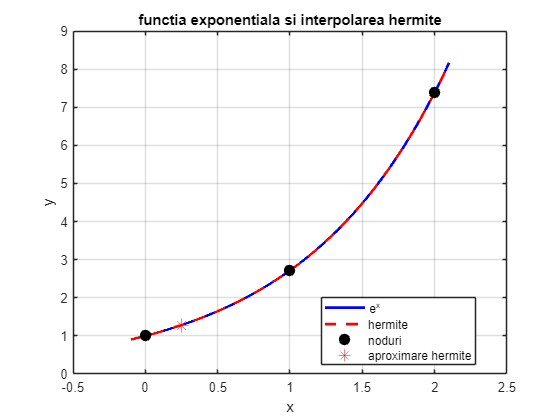


% reprezentam grafic interpolarile pentru o vizualizare comparativa
x_plot = linspace(min(nodes)-0.1, max(nodes)+0.1, 1000); % cream un vector de puncte pentru grafic
y_true = f(x_plot); % calculam valorile functiei exacte pe intervalul x_plot
% calculam valorile polinomului hermite pe intervalul x_plot
y_hermite_plot = hermite_interpolation(x_plot, nodes, f_values, f_prime_values);
% (nota: interpolarea lagrange ar putea fi plotata similar daca se doreste)

figure; % creeaza o noua fereastra grafica
plot(x_plot, y_true, 'b-', 'LineWidth', 2, 'DisplayName', 'e^x'); % deseneaza functia exacta
hold on; % mentine graficul pentru a adauga alte elemente
plot(x_plot, y_hermite_plot, 'r--', 'LineWidth', 2, 'DisplayName', 'hermite'); % deseneaza polinomul hermite
plot(nodes, f_values, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'noduri'); % marcheaza nodurile de interpolare
plot(x_eval, y_hermite, 'r*', 'MarkerSize', 10, 'DisplayName', 'aproximare hermite'); % marcheaza punctul aproximat de hermite
grid on; % adauga grila
legend('Location', 'best'); % afiseaza legenda
title('functia exponentiala si interpolarea hermite'); % seteaza titlul graficului
xlabel('x'); % eticheta axei x
ylabel('y'); % eticheta axei y
hold off; % elibereaza graficul

P2. Utilizati valorile date mai jos pentru a aproxima sin(0.34) utilizand interpolarea Hermite.

x       sin(x)     (sin x)' = cos(x)

0.30    0.29552    0.95534

0.32    0.31457    0.94924

0.35    0.34290    0.93937

Dati o delimitare a erorii si comparati-o cu eroarea exacta. Adaugati datele pentru nodul x = 0.33 si refaceti calculele.

% aproximarea lui sin(0.34) folosind interpolarea hermite
clear; % sterge toate variabilele din workspace-ul curent
clc; % curata fereastra de comanda (command window)

% datele initiale pentru interpolare
nodes = [0.30, 0.32, 0.35]; % definim nodurile de interpolare x_i
f_values = [0.29552, 0.31457, 0.34290]; % valorile functiei f(x_i) = sin(x_i) in noduri
f_prime_values = [0.95534, 0.94924, 0.93937]; % valorile derivatei f'(x_i) = cos(x_i) in noduri

% punctul de evaluare
x_eval = 0.34; % punctul x in care dorim sa aproximam valoarea functiei sin(x)

% interpolarea hermite cu setul initial de noduri
% apelam functia hermite_interpolation (definita si comentata anterior)
y_hermite = hermite_interpolation(x_eval, nodes, f_values, f_prime_values);

% valoarea exacta pentru comparatie
y_exact = sin(x_eval); % calculam valoarea exacta a lui sin(0.34) folosind functia matlab

% afisam rezultatele pentru interpolarea initiala
fprintf('aproximarea lui sin(%.2f) cu 3 noduri:\n', x_eval); % antet pentru afisare

aproximarea lui sin(0.34) cu 3 noduri:


fprintf('interpolarea hermite: %.10f\n', y_hermite); % valoarea aproximata

interpolarea hermite: 0.3334888901


fprintf('valoarea exacta: %.10f\n', y_exact); % valoarea exacta

valoarea exacta: 0.3334870921


fprintf('eroarea: %.10e\n', abs(y_hermite - y_exact)); % eroarea absoluta a aproximarii

eroarea: 1.7979332597e-06



% adaugam un nod nou la x = 0.33 pentru a vedea imbunatatirea aproximarii
nodes_extended = [0.30, 0.32, 0.33, 0.35]; % noul set de noduri, incluzand 0.33
% calculam valorile functiei si derivatei pentru noul set de noduri
f_values_extended = [0.29552, 0.31457, sin(0.33), 0.34290]; % valorile f(x_i), inclusiv sin(0.33)
f_prime_values_extended = [0.95534, 0.94924, cos(0.33), 0.93937]; % valorile f'(x_i), inclusiv cos(0.33)

% interpolarea hermite cu datele extinse (4 noduri)
y_hermite_extended = hermite_interpolation(x_eval, nodes_extended, f_values_extended, f_prime_values_extended);

% afisam rezultatele pentru interpolarea cu nodul aditional
fprintf('\ncu nodul aditional la x = 0.33 (4 noduri):\n'); % antet pentru noua aproximare


cu nodul aditional la x = 0.33 (4 noduri):


fprintf('interpolarea hermite: %.10f\n', y_hermite_extended); % valoarea aproximata cu 4 noduri

interpolarea hermite: 0.3334942290


fprintf('eroarea: %.10e\n', abs(y_hermite_extended - y_exact)); % eroarea absoluta pentru 4 noduri

eroarea: 7.1369057722e-06


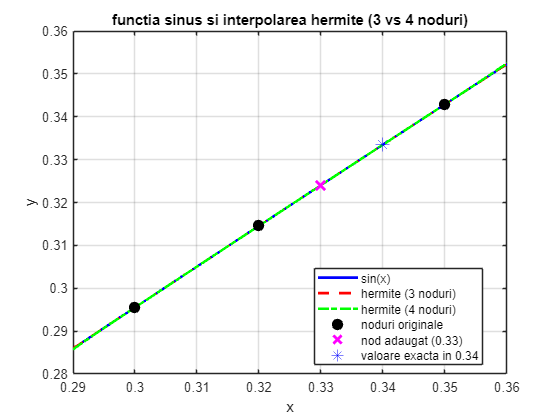


% reprezentam grafic rezultatele pentru o mai buna intelegere
x_plot = linspace(0.29, 0.36, 1000); % cream un vector de puncte pentru grafic, acoperind intervalul nodurilor
y_true = sin(x_plot); % calculam valorile functiei exacte sin(x) pe intervalul x_plot
% calculam polinomul hermite pentru setul initial de noduri pe intervalul x_plot
y_hermite_plot = hermite_interpolation(x_plot, nodes, f_values, f_prime_values);
% calculam polinomul hermite pentru setul extins de noduri pe intervalul x_plot
y_hermite_extended_plot = hermite_interpolation(x_plot, nodes_extended, f_values_extended, f_prime_values_extended);

figure; % creeaza o noua fereastra grafica
plot(x_plot, y_true, 'b-', 'LineWidth', 2, 'DisplayName', 'sin(x)'); % deseneaza functia exacta sin(x)
hold on; % mentine graficul pentru a adauga alte elemente
plot(x_plot, y_hermite_plot, 'r--', 'LineWidth', 2, 'DisplayName', 'hermite (3 noduri)'); % deseneaza interpolarea cu 3 noduri
plot(x_plot, y_hermite_extended_plot, 'g-.', 'LineWidth', 2, 'DisplayName', 'hermite (4 noduri)'); % deseneaza interpolarea cu 4 noduri (linie verde punctata)
plot(nodes, f_values, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k', 'DisplayName', 'noduri originale'); % marcheaza nodurile originale
plot(0.33, sin(0.33), 'mx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'nod adaugat (0.33)'); % marcheaza nodul adaugat cu 'x' magenta
plot(x_eval, y_exact, 'b*', 'MarkerSize', 10, 'DisplayName', 'valoare exacta in 0.34'); % marcheaza valoarea exacta in punctul de evaluare
grid on; % adauga grila la grafic
legend('Location', 'best'); % afiseaza legenda in cea mai buna pozitie
title('functia sinus si interpolarea hermite (3 vs 4 noduri)'); % seteaza titlul graficului
xlabel('x'); % eticheta pentru axa x
ylabel('y'); % eticheta pentru axa y
hold off; % elibereaza graficul

P3. Un automobil care se deplaseaza pe un drum drept este cronometrat in mai multe puncte. Datele de observatie se dau in tabela de mai jos. Utilizati interpolarea Hermite pentru a prevedea pozitia si viteza automobilului la momentul t = 10.

Timpul:     0      3      5       8       13

Distanta:   0     225  383  623   993

Viteza:     75    77    80     74     72

% predictia pozitiei si vitezei automobilului folosind interpolarea hermite
clear; % sterge toate variabilele din workspace
clc; % curata fereastra de comanda

% datele date (timp, distanta parcursa si viteza instantanee)
time = [0, 3, 5, 8, 13]; % vectorul momentelor de timp (in secunde) la care se fac masuratorile
distance = [0, 225, 383, 623, 993]; % vectorul distantelor parcurse (in metri) corespunzatoare momentelor de timp
velocity = [75, 77, 80, 74, 72]; % vectorul vitezelor instantanee (in metri/secunda) la momentele de timp respective

% momentul de timp pentru care dorim sa facem predictia
t_eval = 10; % (in secunde)

% interpolarea hermite pentru a gasi pozitia la t_eval
% folosim 'time' ca noduri, 'distance' ca valori ale functiei (pozitiei)
% si 'velocity' ca valori ale derivatei functiei (vitezei)
position = hermite_interpolation(t_eval, time, distance, velocity);

% interpolarea hermite pentru a gasi viteza la t_eval
% folosim functia 'hermite_interpolation_derivative' care calculeaza derivata polinomului hermite
velocity_at_t = hermite_interpolation_derivative(t_eval, time, distance, velocity);

% afisam rezultatele predictiilor
fprintf('la momentul t = %.2f secunde:\n', t_eval);

la momentul t = 10.00 secunde:


fprintf('pozitia preconizata: %.2f metri\n', position);

pozitia preconizata: 742.50 metri


fprintf('viteza preconizata: %.2f metri/secunda\n', velocity_at_t);

viteza preconizata: 48.38 metri/secunda


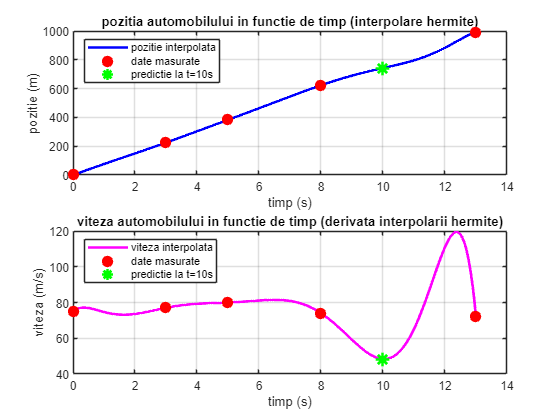


% pregatim date pentru reprezentarea grafica a pozitiei
t_plot = linspace(min(time), max(time), 1000); % cream un vector de timpuri mai dens pentru un grafic neted
% calculam pozitiile interpolate pentru toate punctele din t_plot
position_plot = hermite_interpolation(t_plot, time, distance, velocity);

figure; % creeaza o noua fereastra grafica
subplot(2,1,1); % imparte fereastra grafica in 2 randuri, 1 coloana, si selecteaza primul grafic (cel de sus)
plot(t_plot, position_plot, 'b-', 'LineWidth', 2); % deseneaza curba pozitiei interpolate
hold on; % mentine graficul pentru a adauga elemente suplimentare
plot(time, distance, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % marcheaza punctele de date originale pentru pozitie
plot(t_eval, position, 'g*', 'MarkerSize', 10, 'LineWidth', 2); % marcheaza pozitia preconizata la t_eval
grid on; % adauga o grila
title('pozitia automobilului in functie de timp (interpolare hermite)');
xlabel('timp (s)');
ylabel('pozitie (m)');
legend('pozitie interpolata', 'date masurate', 'predictie la t=10s', 'Location', 'northwest');

% pregatim date pentru reprezentarea grafica a vitezei
velocity_plot = zeros(size(t_plot)); % initializeaza un vector pentru vitezele interpolate
for i = 1:length(t_plot) % iteram prin fiecare punct din t_plot
    % calculam viteza interpolata in fiecare punct t_plot(i)
    velocity_plot(i) = hermite_interpolation_derivative(t_plot(i), time, distance, velocity);
end

subplot(2,1,2); % selecteaza al doilea grafic (cel de jos)
plot(t_plot, velocity_plot, 'm-', 'LineWidth', 2); % deseneaza curba vitezei interpolate (cu magenta)
hold on; % mentine graficul
plot(time, velocity, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % marcheaza punctele de date originale pentru viteza
plot(t_eval, velocity_at_t, 'g*', 'MarkerSize', 10, 'LineWidth', 2); % marcheaza viteza preconizata la t_eval
grid on; % adauga o grila
title('viteza automobilului in functie de timp (derivata interpolarii hermite)');
xlabel('timp (s)');
ylabel('viteza (m/s)');
legend('viteza interpolata', 'date masurate', 'predictie la t=10s', 'Location', 'northwest');
hold off; % elibereaza graficul